# Trajectory planning

## Task B: Cubic Trajectory

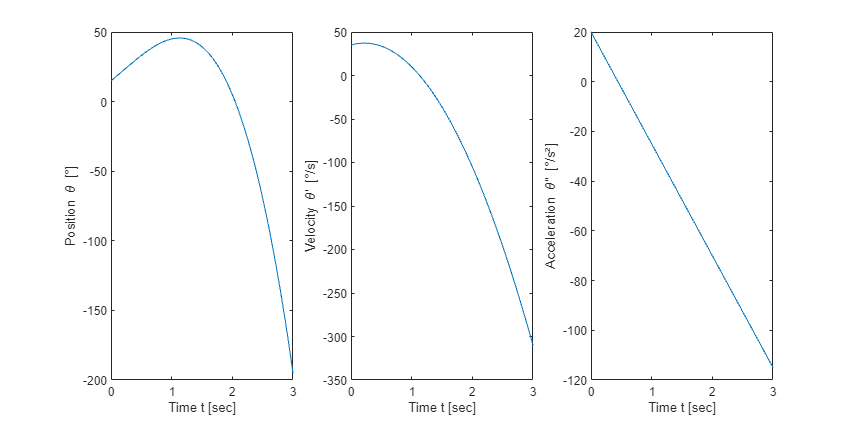

close all;
clear;
clc;

% Cubic trajectory function
theta = @(t) 15 + 35.*t + 10.*t.^2 - 15.*t.^3;

% Time array from 0 to 3 sec's
t = 0:0.01:3;

% Velocity
theta_dot = @(t) 35 + 2*10.*t - 3*15.*t.^2;

% Acceleration
theta_ddot = @(t) 20 - 45.*t;

%% PLOTS
figure(Position=[0 0 1000 500])
subplot(1,3,1)
plot(t,theta(t))
xlabel('Time t [sec]')
ylabel('Position \theta [°]')

subplot(1,3,2)
plot(t,theta_dot(t))
xlabel('Time t [sec]')
ylabel('Velocity \theta\prime [°/s]')

subplot(1,3,3)
plot(t,theta_ddot(t))
xlabel('Time t [sec]')
ylabel('Acceleration \theta\prime\prime [°/s²]')

## Task C: Cubic trajectory planning

clear;
clc;

To calculate the optimal trajectory, which goes through $\theta$ = 25° (via point) the so-called "Cubic Polynomials With via Points"-method will be used. The angular position of these two intervalls is decribed by:


$$\begin{array}{l}
\theta_1 \left(t\right)=a_{10} +a_{11} t+a_{12} t^2 +a_{13} t^3 \\
\theta_2 \left(t\right)=a_{20} +a_{21} t+a_{22} t^2 +a_{23} t^3 
\end{array}$$


To have a smooth position trajectory, velocity and acceleration the velocity and acceleration at the via point have to equal:


$$\dot{\;\theta_1 } \left(t=t_{\mathrm{f1}} =1s\right)=\dot{\;\theta_2 } \left(t=0s\right)\Rightarrow a_{11} +2a_{12} t_{\mathrm{f1}} +3a_{13} t_{\mathrm{f1}}^2 =a_{21}$$



$$\ddot{\;\theta_1 } \left(t=t_{\mathrm{f1}} =1s\right)=\ddot{\theta_2 } \left(t=0s\right)\Rightarrow 2a_{12} +6a_{13} t_{\mathrm{f1}} =2a_{22}$$


The usual constraints like zero velocity are used:


$$\dot{\;\theta_1 } \left(t=0s\right)=0=a_{11}$$



$$\dot{\;\theta_2 } \left(t=t_{\mathrm{f2}} =4-1s\right)=0=a_{21} +2a_{22} t_{\mathrm{f2}} +3a_{23} t_{\mathrm{f2}}^2$$


With the help of this constraints a linear system of equations can be formulated and the coefficients of the two cubics solved (see Function "getCubicVia" for detail):


$$X=\left\lbrack \begin{array}{c}
a_{12} \\
a_{13} \\
a_{21} \\
a_{22} \\
a_{23} 
\end{array}\right\rbrack$$


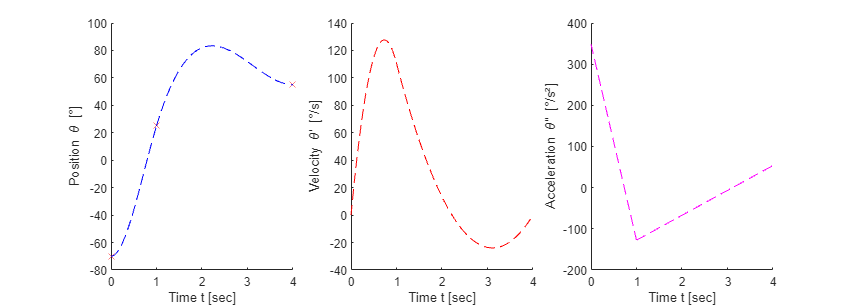


% Define query points
theta0 = -70;
theta1 = 25;
theta2 = 55;
t1 = 1;
t2 = 4;

% Get cubic trajectories
T01 = 0:0.01:t1;
T12 = t1:0.01:t2;
% [THETA01,THETA01_dot,THETA01_ddot] = getCubicTraj(T01,t1,theta0,theta1);
% [THETA12,THETA12_dot,THETA12_ddot] = getCubicTraj(T12-t1,t2-t1,theta1,theta2);

[THETA1, THETA2, THETA1_dot, THETA2_dot, THETA1_ddot, THETA2_ddot] = getCubicVia(T01,T12-t1,theta0,theta1,theta2,t1,t2-t1);

figure('Position',[10 10 1400 500])
subplot(1,3,1)
hold on
plot(0, -70, 'rx')
plot(t1, 25, 'rx')
plot(t2, 55, 'rx')
% plot(T01, THETA01,'b-')
% plot(T12, THETA12,'b-')
plot(T01, THETA1,'b--')
plot(T12, THETA2,'b--')
hold off

xlabel('Time t [sec]')
ylabel('Position \theta [°]')

subplot(1,3,2)
hold on
% plot(T01, THETA01_dot,'r-')
% plot(T12, THETA12_dot,'r-')
plot(T01, THETA1_dot,'r--')
plot(T12, THETA2_dot,'r--')
hold off

xlabel('Time t [sec]')
ylabel('Velocity \theta\prime [°/s]')

subplot(1,3,3)
hold on
% plot(T01, THETA01_ddot,'m-')
% plot(T12, THETA12_ddot,'m-')
plot(T01, THETA1_ddot,'m--')
plot(T12, THETA2_ddot,'m--')
hold off
xlabel('Time t [sec]')
ylabel('Acceleration \theta\prime\prime [°/s²]')

## Sources:

Dr.-Ing. John Nassour, "Trajectory Generation". Artificial Intelligence & Neuro Cognitive Systems FakultätfürInformatik. Technische Universität Chemnitz. 11.01.2017